# Phase Portrait for Duffing's Equation

clear; close all; clc

% creates two matrices:
% one for all the x-values on the grid (constant columns)
% one for all the y-values on the grid (constant rows)
y1 = linspace(-2,2,20);
y2 = linspace(-2,2,20);
[X,Y] = meshgrid(y1,y2);

Computing the Vector Field

% Generate two matrices, u and v. 
% U contains the value of y1'(0) at each x and y position
% V contains the value of y2'(0) at each x and y position
U = zeros(size(X));
V = zeros(size(X));
t = 0;

% numel iterates over the 1st column, then 2nd, ...
for i = 1:numel(X)
    y_dot = f(t, [X(i); Y(i)]); % pendulum equation
    U(i) = y_dot(1);
    V(i) = y_dot(2);
end

Plot the Vector Field

quiver(X,Y,U,V,'k');
xlabel('x')
ylabel('y')
axis tight equal;
title("Vector Field for Duffing's Equation")

Plotting solutions on the vector field for different initial conditions:

 
$$y_1(0)=y_{10}, \\
y_2(0)=y_{20}$$


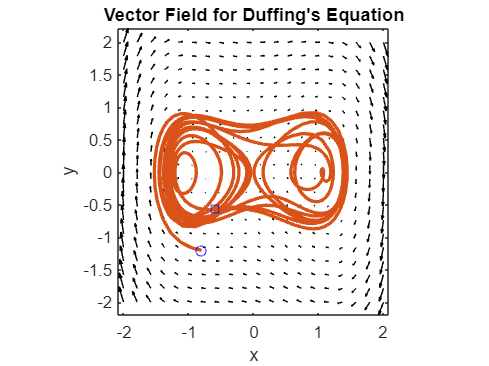

hold on
y10 = -0.8;
y20 = -1.2;
[ts,ys] = ode45(@f,[0 100],[y10; y20]);
plot(ys(:,1),ys(:,2),'LineWidth',2)
plot(ys(1,1),ys(1,2),'bo') % starting point
plot(ys(end,1),ys(end,2),'bs') % starting point
hold off

Now plot the time series:

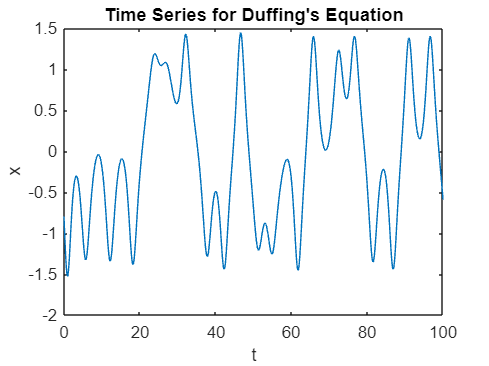

plot(ts, ys(:,1))
title("Time Series for Duffing's Equation")
xlabel('t')
ylabel('x')

Let $$y_1=x$ and $y_2=y$$.

function [y_dot] = f(t,y)
gamma=0.3;
omega=1;
delta=0.16;
y_dot(1,:) = y(2);
y_dot(2,:) = y(1)-y(1)^3-delta*y(2)+gamma*cos(omega*t);
end